% Load CSV dataset manually
filename = "C:\Users\geode\Downloads\prosthetics_optimization_dataset.csv";
data = csvread(filename, 1, 0);  % Skips the first row if it's a header

% Step 2: Extract Features (Force Output & Battery Consumption)
force_output = data(:,1);  % First column
battery_consumption = data(:,2);  % Second column

% Step 3: Combine Data
prosthetic_data = [force_output, battery_consumption];

% Step 4: Apply K-Means++ (k=3)
[idx, centroids] = kmeans(prosthetic_data, 3, 'Start', 'plus');

% Step 5: Display Clusters
disp('Cluster Centers:');

Cluster Centers:


disp(centroids);

  204.1250   91.8750
  122.0000   51.1667
   52.5000   20.5000



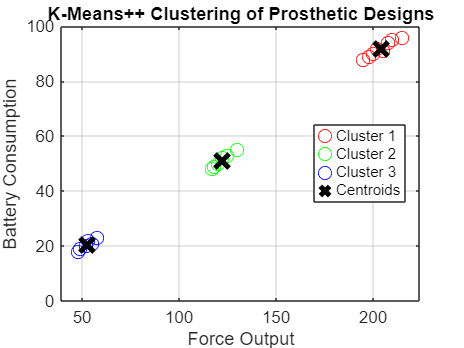


% Step 6: Visualize
figure;
gscatter(force_output, battery_consumption, idx, 'rgb', 'o', 8);
hold on;
plot(centroids(:,1), centroids(:,2), 'kx', 'MarkerSize', 12, 'LineWidth', 3);
xlabel('Force Output');
ylabel('Battery Consumption');
title('K-Means++ Clustering of Prosthetic Designs');
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Centroids');
grid on;
hold off;